# Actividad 2 (Análisis de Robot lineal de 3GDL)

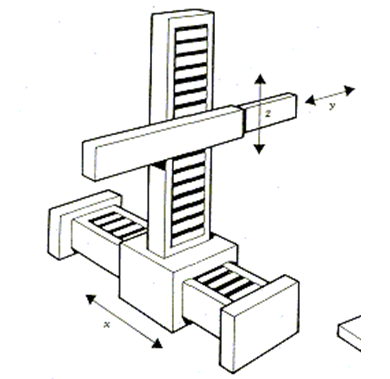

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms l1(t) l2(t) l3(t) t 

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [l1, l2, l3];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(l1(t), l2(t), l3(t))




%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d         d         d       \
| -- l1(t), -- l2(t), -- l3(t) |
\ dt        dt        dt       /



%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0 ; 0; l1];
%Matriz de rotación de la junta 1 respecto a 0.... -90º y1 
R(:,:,1)= [0  0 -1;
           0  1  0;
           1  0  0];


%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; l3 ; l2];
%Matriz de rotación de la junta 2 respecto a 1  -90º y1 
R(:,:,2)= [1  0 0;
           0  0 1;
           0 -1 0];

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0 ; 0];
%Matriz de rotación de la junta 3 respecto a 2   
R(:,:,3)= [1  0 0;
           0  1 0;
           0  0 1];



%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    %disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    %pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________ \
|    d       |
| - -- l2(t) |
|   dt       |
|            |
|  ________  |
|   d        |
|  -- l3(t)  |
|  dt        |
|            |
|  ________  |
|   d        |
|  -- l1(t)  |
\  dt        /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



En este codigo se realizaron traslaciones y rotaciones, de acuerdo a la imagen inicial, estas transformaciones se realizaron de tal forma que al rotar la traslacion siempre fuera en Z, pero en la velocidad lineal en los tres ejes estan las traslaciones (l1, l2 y l3) aunque se realizaron en el eje Z, esto es debido al marco de referencia inercial y a que es una junta prismatica

marco de referencia inercial: 

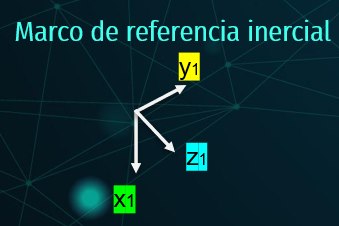

Como se puede apreciar, l1 que es la primera traslacion se encuentra en el eje Z del marco de referencia inercial y es positivo, l2 esta en el eje X pero negativo, por eso aparece en la velocidad en X con negativo y por ultimo la traslacion de l3 esta en el eje Y del marco inercial y positivo. Por eso del resultado de la velocidad lineal de las junstas prismaticas.

En cuanto a la velocidad angular es 0 en los tres ejes, debido a que el tipo de robot es lineal y no de rotacion